# Specification of the Filter

fsamp = 4600;  % sampling frequency is  4600 rad/s
fcuts = [900 1200 1700 1900]; % passband and stopband edges
mags = [0 1 0];
devs = [db2mag(-58) db2mag(0.14) db2mag(-58)]; % passband ripple = 0.14dB & stopband ripple = 58dB


## Desining the Kaiser window

[n,Wn,beta,ftype] = kaiserord(fcuts,mags,devs,fsamp);
n = n + rem(n,2);
hh = fir1(n,Wn,ftype,kaiser(n+1,beta),'noscale');
n

n = 82

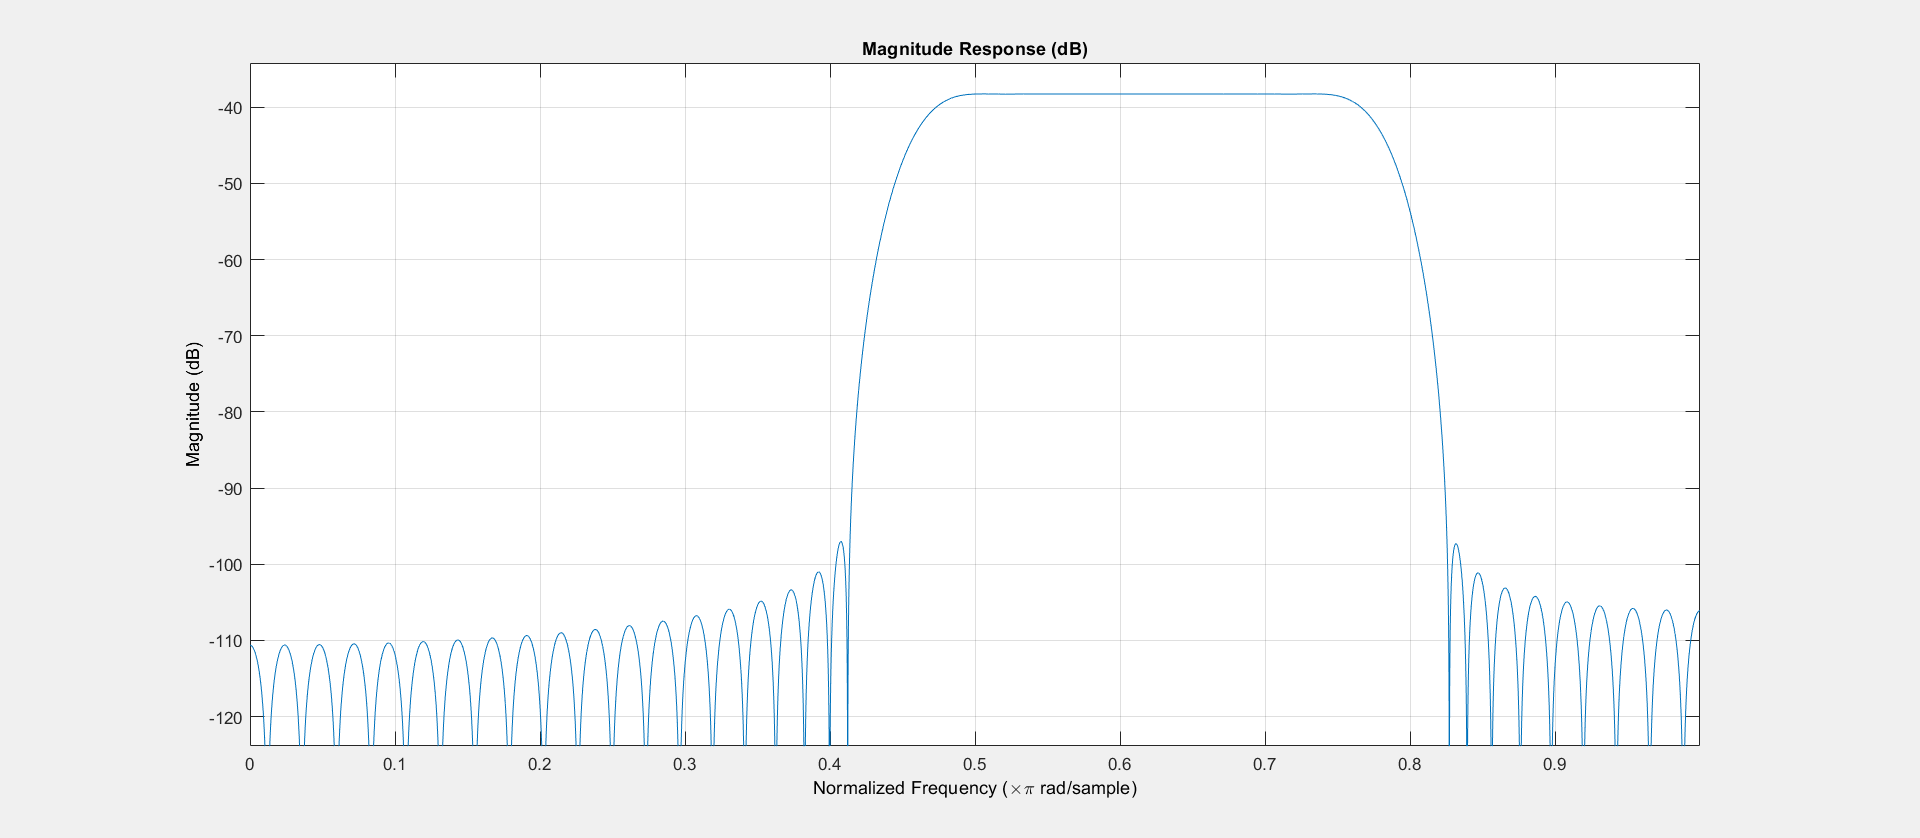

fvtool(hh,n);

filtord(hh)

ans = 82

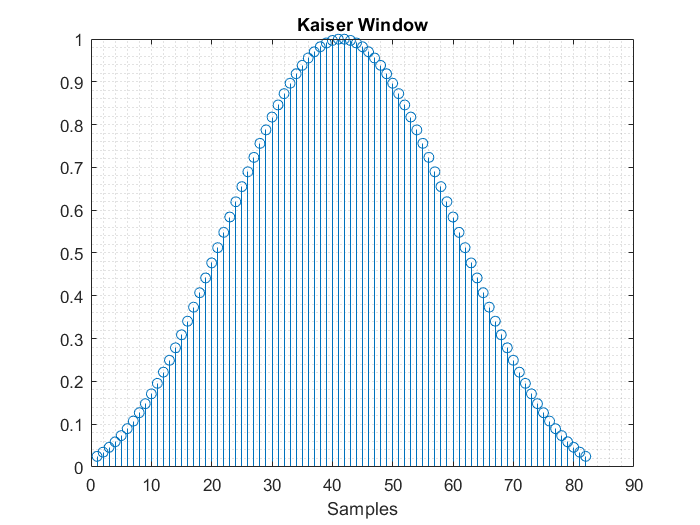

figure;
stem(kaiser(n,beta))
title("Kaiser Window")
xlabel("Samples")
grid minor

## Impilse response of the filter

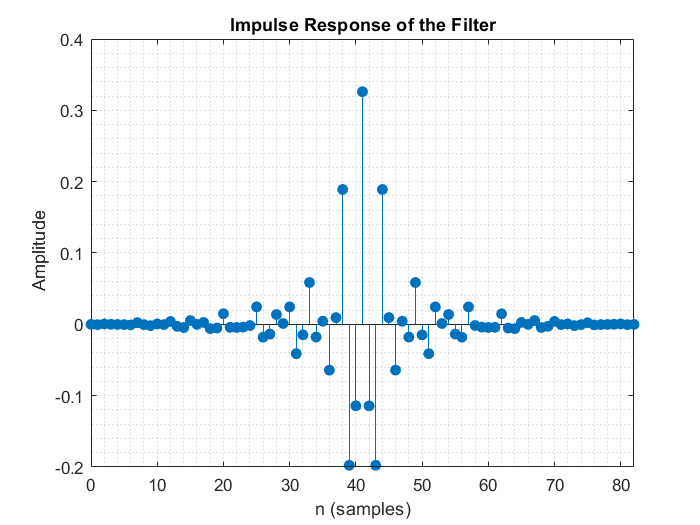

figure;
impz(hh)
title("Impulse Response of the Filter")
grid minor

## Magnitude response of the filter

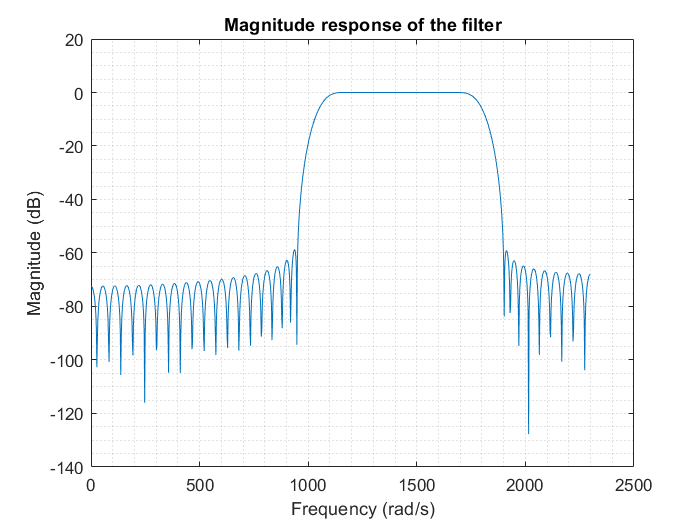

figure;
[H,f] = freqz(hh,1,1024,fsamp);
plot(f,(mag2db(abs(H))))
title("Magnitude response of the filter")
xlabel("Frequency (rad/s)")
ylabel("Magnitude (dB)")
grid minor

## Magnitude response in the passband

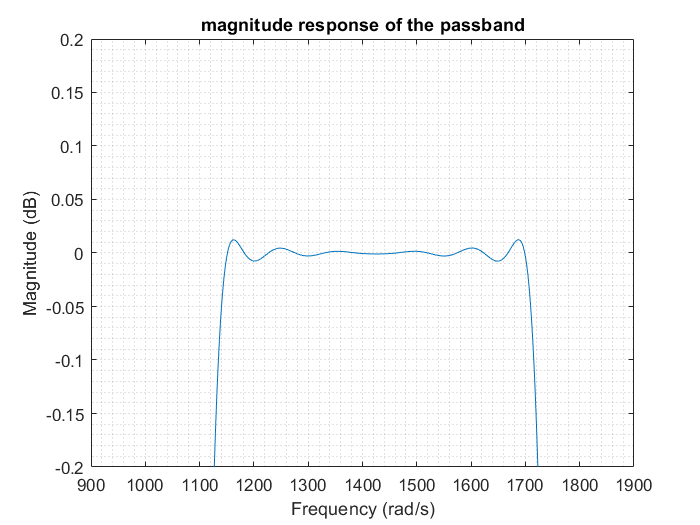

figure;
[H,f] = freqz(hh,1,1024,fsamp);
plot(f,(mag2db(abs(H))))
axis([900 , 1900 , -0.2 , 0.2]);
title("magnitude response of the passband")
xlabel("Frequency (rad/s)")
ylabel("Magnitude (dB)")
grid minor